clear
clc

## Bayes classifier for iris dataset

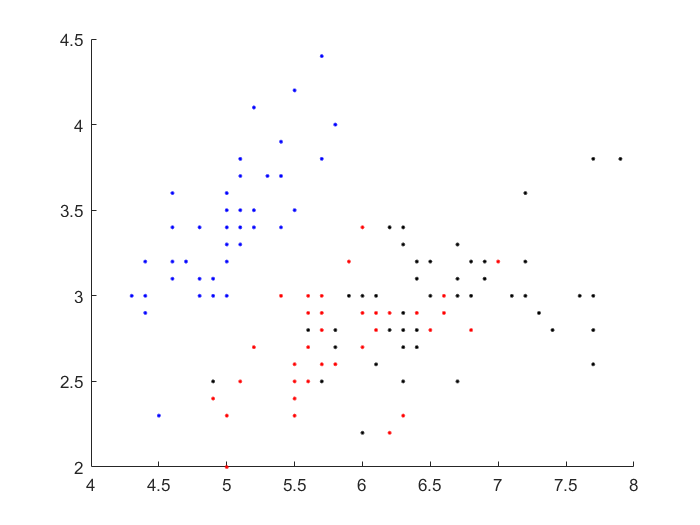


data = iris_dataset;
% show the first two dimensions
figure(1)
hold on
plot(data(1,1:50),data(2,1:50),'b.','LineWidth',1.5);
plot(data(1,51:100),data(2,51:100),'r.','LineWidth',1.5);
plot(data(1,101:150),data(2,101:150),'k.','LineWidth',1.5);


x = data(1:2,:);

% Label
gnd = [ones(1,50),ones(1,50)*2,ones(1,50)*3];

% Training set and test set
seq = randperm(150);
trainnum = 100;
Train = x(:,seq(1:trainnum));
gnd_T = gnd(seq(1:trainnum));
Test = x(:,seq(trainnum+1:end));
gnd_Test = gnd(seq(trainnum+1:end));

% Compute the conditional probabilities and prior probabilities
[pw,my_m,my_cov] = my_bayes(Train,gnd_T);

% get the label and the posterior probabilities
[post_p,test_lab] = my_testbayes(Test,pw,my_m,my_cov,3);
right = gnd_Test == test_lab;
% compute the accuracy
rate = sum(right)/length(gnd_Test);
disp(['Bayes classifier Accuracy:' num2str(rate)]);

Bayes classifier Accuracy:0.74


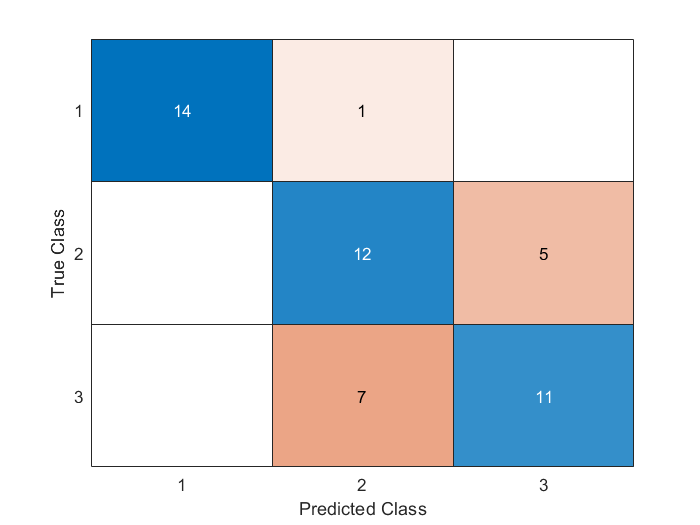


% compute the confusionmatrix
figure;
cm = confusionchart(gnd_Test,test_lab);

## Performance evaluation using ROC curve

clear
% ROC curve is designed for binary classification
data = iris_dataset;
xb = data(1:2,51:150);
gnd = [ones(1,50),ones(1,50)*2];
seq = randperm(100);
trainnum = 30;
Train = xb(:,seq(1:trainnum));
gnd_T = gnd(seq(1:trainnum));
Test = xb(:,seq(trainnum+1:end));
gnd_Test = gnd(seq(trainnum+1:end));

% Compute the conditional probabilities and prior probabilities
[pw,my_m,my_cov] = my_bayes(Train,gnd_T);

% get the label and the posterior probabilities
[post_p,test_lab] = my_testbayes(Test,pw,my_m,my_cov,2);
right = gnd_Test == test_lab;
% compute the accuracy
rate = sum(right)/length(gnd_Test);
disp(['Bayes classifier Accuracy:' num2str(rate)]);

Bayes classifier Accuracy:0.58571


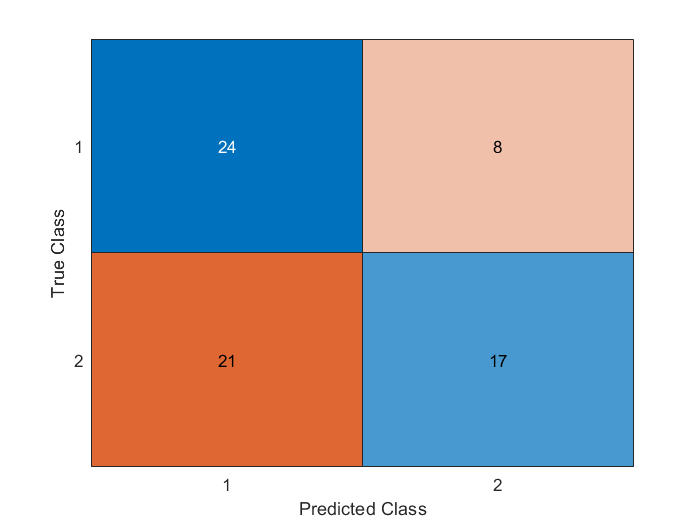


% compute the confusionmatrix
figure;
cm = confusionchart(gnd_Test,test_lab);

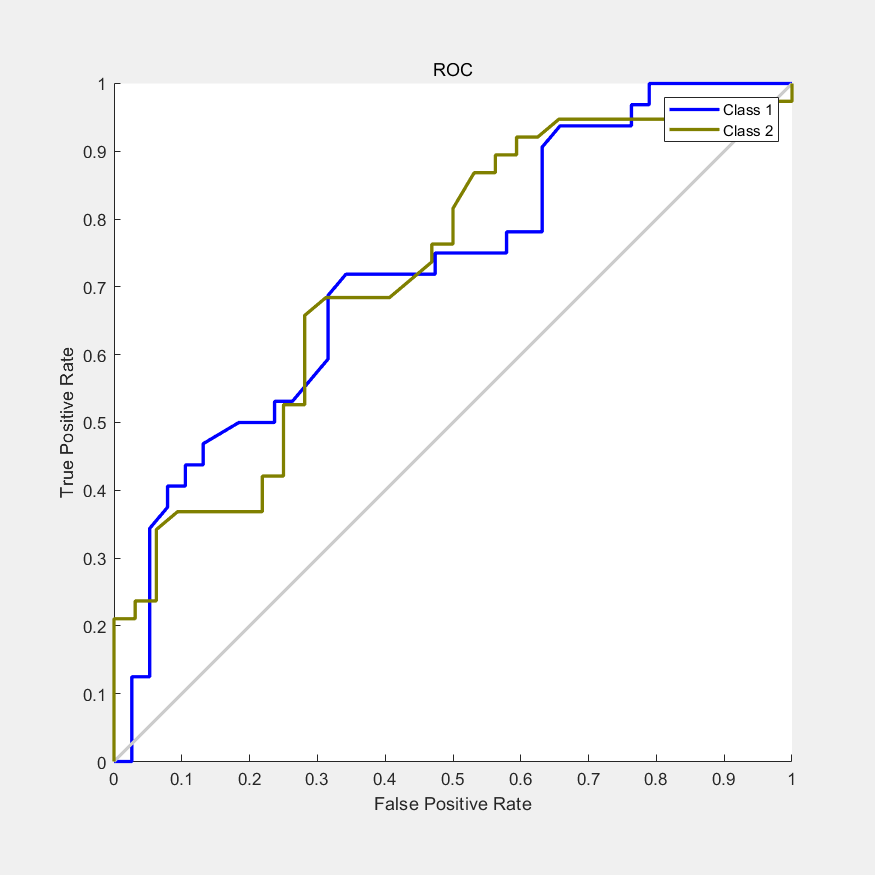


% plotroc
% in plotroc, the onehot groundtruth is neeed
a = eye(max(gnd_Test));
gnd_onehot = a(gnd_Test,:);

plotroc(gnd_onehot',post_p');

## Visualize Decision Surfaces of Bayes classifier

clear
data = iris_dataset;
% show the first two dimensions

x = data(1:2,:);

% Label
gnd = [ones(1,50),ones(1,50)*2,ones(1,50)*3];

% Training set and test set
seq = randperm(150);
trainnum = 100;
Train = x(:,seq(1:trainnum));
gnd_T = gnd(seq(1:trainnum));
Test = x(:,seq(trainnum+1:end));
gnd_Test = gnd(seq(trainnum+1:end));

% Compute the conditional probabilities and prior probabilities
[pw,my_m,my_cov] = my_bayes(Train,gnd_T);

% get the label and the posterior probabilities
[post_p,test_lab] = my_testbayes(Test,pw,my_m,my_cov,3);
right = gnd_Test == test_lab;
% compute the accuracy
rate = sum(right)/length(gnd_Test);
disp(['Bayes classifier Accuracy:' num2str(rate)]);

Bayes classifier Accuracy:0.82


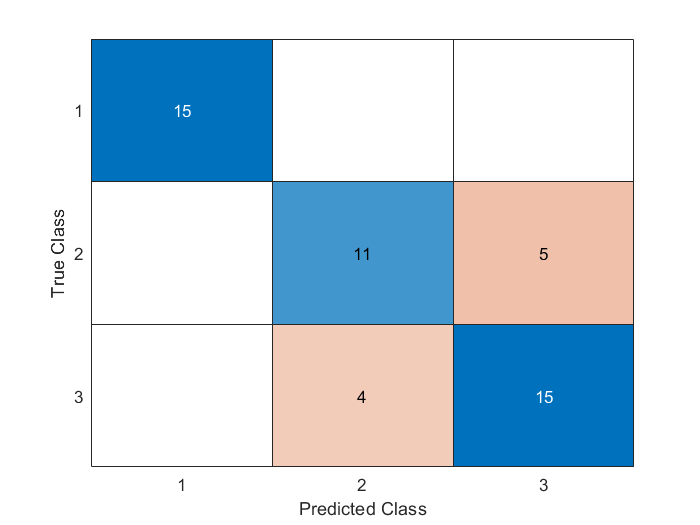


% compute the confusionmatrix
figure;
cm = confusionchart(gnd_Test,test_lab);

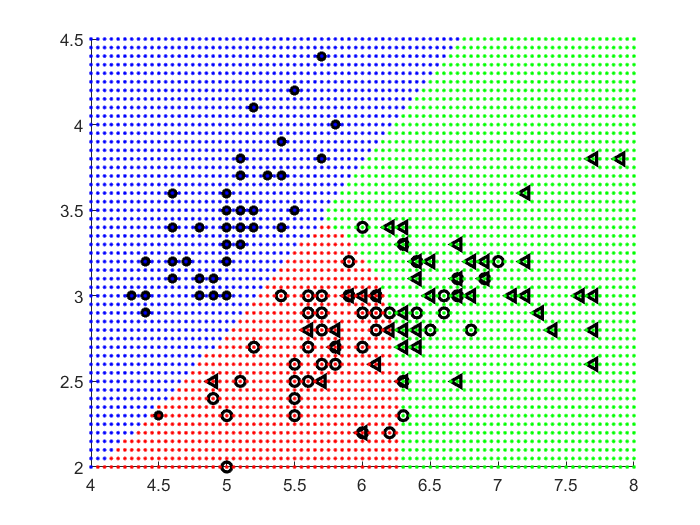


% draw decision surface
figure
hold on
plot(data(1,1:50),data(2,1:50),'k*','LineWidth',2);
plot(data(1,51:100),data(2,51:100),'ko','LineWidth',2);
plot(data(1,101:150),data(2,101:150),'k<','LineWidth',2);
for i = 4:0.05:8
    for j = 2:0.05:4.5
        temp = [i;j];
        [post_p,test_lab] = my_testbayes(temp,pw,my_m,my_cov,3);
        if test_lab ==1
            plot(i,j,'b.','linewidth',2);
        elseif test_lab == 2
            plot(i,j,'r.','linewidth',2);
        else
            plot(i,j,'g.','linewidth',2);
        end
    end
end

function [pw,my_m,my_cov] = my_bayes(x,gnd)
    [row,~] = size(x);
    my_lab = unique(gnd);
    numClass = length(my_lab);
    % compute the prior
    for i = 1 : numClass
        pw(i)= sum(gnd==my_lab(i));
        pw(i) = pw(i)/length(gnd);
    end
    % compute mean and cov
    for j = 1:numClass
        temp = x(:,gnd==my_lab(j));
        my_m{j} =mean(temp,2) ;
        my_cov{j} = cov(temp');
    end    
end

function [post_p,test_lab] = my_testbayes(xt,pw,mu,sigma,numClass)

    [~,len] = size(xt);
    for k = 1 : len
        temp = xt(:,k);
        for i = 1: numClass
            prod = mvnpdf(temp,mu{i},sigma{i});
            post_p(k,i) = prod*pw(i);
        end
        post_p(k,:) = post_p(k,:)./sum(post_p(k,:));
        [~,inx] = max(post_p(k,:));
        test_lab(k) = inx; 
    end
end